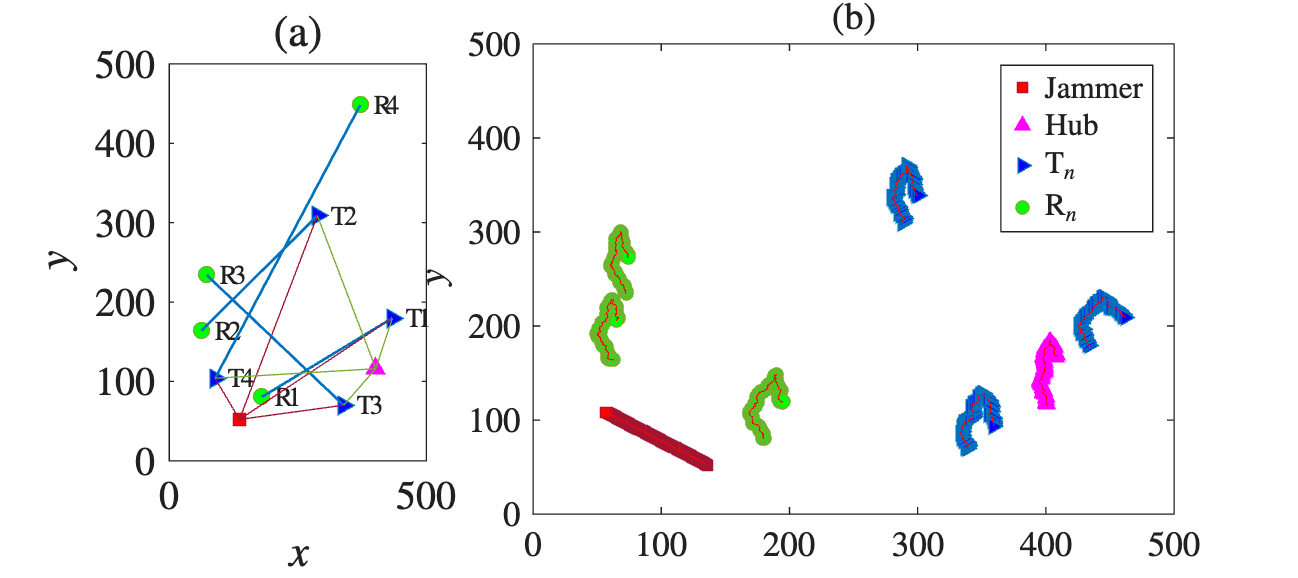

%% Parameters

clear all
close all

% New colors
blue1=[0, 0.4470, 0.7410];
orange1=[0.8500, 0.3250, 0.0980];
yellow1=[0.9290, 0.6940, 0.1250];
purple1=[0.4940, 0.1840, 0.5560];
green1=[0.4660, 0.6740, 0.1880];
cyan1=[0.3010, 0.7450, 0.9330];
red1=[0.6350, 0.0780, 0.1840];

%%

subplot(1,3,1); % Changed to 1x3 grid, first position

N = 4; % number of pairs of users (links)

%% MOBILITY MODEL-based

% Assigning positions
%--------------------

pos_jammer = load('data_pos_RWP.csv');
pos_nodes = load('data_pos_RPGM.csv');

NUM_POSITIONS = 1; % mobility 

pos_J = pos_jammer(1:NUM_POSITIONS, :); % Jammer

pos_Tx0 = pos_nodes(1:NUM_POSITIONS, 1:2); % the Hub
% pos_Rx0 = pos_nodes(:, 3:4); % unused!

pos_Tx1 = pos_nodes(1:NUM_POSITIONS, 5:6); % position of Tx1
pos_Rx1 = pos_nodes(1:NUM_POSITIONS, 7:8); % position of Rx1

pos_Tx2 = pos_nodes(1:NUM_POSITIONS, 9:10); % position of Tx2
pos_Rx2 = pos_nodes(1:NUM_POSITIONS, 11:12); % position of Rx2

pos_Tx3 = pos_nodes(1:NUM_POSITIONS, 13:14); % position of Tx3
pos_Rx3 = pos_nodes(1:NUM_POSITIONS, 15:16); % position of Rx3

pos_Tx4 = pos_nodes(1:NUM_POSITIONS, 17:18); % position of Tx4
pos_Rx4 = pos_nodes(1:NUM_POSITIONS, 19:20); % position of Rx4

pos_Tx5 = pos_nodes(1:NUM_POSITIONS, 20:21); % position of Tx4
pos_Rx5 = pos_nodes(1:NUM_POSITIONS, 22:23); % position of Rx4

% Compute location of nodes
% pos_source = [x_source, y_source];
pos_source_all = [pos_Tx1; pos_Tx2; pos_Tx3; pos_Tx4; pos_Tx5];
pos_source = pos_source_all(1:N, :);

% pos_des = [x_des, y_des];
pos_des_all = [pos_Rx1; pos_Rx2; pos_Rx3; pos_Rx4; pos_Rx5];
pos_des = pos_des_all(1:N, :);
pos_jammer = pos_J;

% ----------

x_source = pos_source(:,1);
y_source = pos_source(:,2);

x_des = pos_des(:,1);
y_des = pos_des(:,2);

x_jammer = pos_jammer(:,1);
y_jammer = pos_jammer(:,2);

x_ccch = pos_Tx0(:,1);
y_ccch = pos_Tx0(:,2);
%%
% for legend

num_pos=numel(x_source);
% Jammer
plot(NaN, NaN, 'rs', 'Color', red1, 'MarkerFace', 'r', 'Color', red1); hold on
% Hub
plot(NaN, NaN, 'm^', 'MarkerFace', 'm'); hold on
% Tx
plot(NaN, NaN, 'b>', 'markerface', 'b', 'Color', blue1, 'MarkerFace', 'b', 'Color', blue1); hold on
% Rx
plot(NaN, NaN, 'go', 'markerface', 'g', 'Color', green1, 'MarkerFace', 'g', 'Color', green1); hold on

% For real plot

plot(x_jammer, y_jammer, 'rs', 'Color', red1, 'MarkerFace', 'r', 'Color', red1); hold on
% text(x_jammer+5, y_jammer, 'Jammer')

plot(x_ccch, y_ccch, 'm^', 'MarkerFace', 'm'); hold on
% text(x_ccch+5, y_ccch, 'Hub')

for jj=1:num_pos
    plot(x_source(jj), y_source(jj), 'b>', 'markerface', 'b', 'Color', blue1, 'MarkerFace', 'b', 'Color', blue1); hold on
    text(x_source(jj)+20, y_source(jj), '$\mathrm{T}$', 'Interpreter', 'latex'); hold on
    text(x_source(jj)+45, y_source(jj), ['$' num2str(jj) '$'], 'Interpreter', 'latex'); hold on
    
    plot(x_des(jj), y_des(jj), 'go', 'markerface', 'g', 'Color', green1, 'MarkerFace', 'g', 'Color', green1); hold on
    text(x_des(jj)+20, y_des(jj), '$\mathrm{R}$', 'Interpreter', 'latex'); hold on
    text(x_des(jj)+45, y_des(jj), ['$' num2str(jj) '$'], 'Interpreter', 'latex'); hold on
end

for pp = 1:num_pos
    plot([x_source(pp), x_des(pp)], [y_source(pp), y_des(pp)], 'b-', 'Color', blue1, 'LineWidth', 1); hold on
    plot([x_source(pp), x_jammer], [y_source(pp), y_jammer], 'r-', 'Color', red1); hold on
    plot([x_source(pp), x_ccch], [y_source(pp), y_ccch], 'g-', 'Color', green1); hold on
end


xlabel('$x$', 'Interpreter', 'Latex')
ylabel('$y$', 'Interpreter', 'Latex')
title('(a)', 'Interpreter', 'Latex')
% legend ('Jammer', 'Hub', '$\mathrm{T}_n$', '$\mathrm{R}_n$', ...
%     'Interpreter', 'Latex', ...
%     'Location', 'nw')
axis([0 500 0 500])

% Set tick labels to LaTeX
set(gca, 'TickLabelInterpreter', 'latex');
set(gca,'FontSize',15)
% set(gca, 'LooseInset', get(gca, 'TightInset')) %remove plot padding

%% 

subplot(1,3,[2 3]); % Changed to occupy positions 2 and 3 (2/3 of width)

%% Jammer
pos_jammer = load('data_pos_RWP.csv');

vX = pos_jammer(:,1); 
vY = pos_jammer(:,2); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
jammer = plot(vX, vY, 'rs', 'markerface', 'r', 'color', red1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;

%%
pos_nodes = load('data_pos_RPGM.csv');

%% Controller Tx0
vX = pos_nodes(:,1); 
vY = pos_nodes(:,2); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Tx0 = plot(vX, vY, 'm^', 'markerface', 'm', 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;

%% Tx1
vX = pos_nodes(:,5); 
vY = pos_nodes(:,6); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Tx1 = plot(vX, vY, 'b>', 'markerface', 'b', 'color', blue1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;

%% Rx1
vX = pos_nodes(:,7); 
vY = pos_nodes(:,8); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Rx1 = plot(vX, vY, 'go', 'markerface', 'g', 'color', green1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;

%% Tx2
vX = pos_nodes(:,9); 
vY = pos_nodes(:,10); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Tx2 = plot(vX, vY, 'b>', 'markerface', 'b', 'color', blue1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;
grid on

%% Rx2
vX = pos_nodes(:,11); 
vY = pos_nodes(:,12); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Rx2 = plot(vX, vY, 'go', 'markerface', 'g', 'color', green1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;

%% Tx3
vX = pos_nodes(:,13); 
vY = pos_nodes(:,14); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Tx3 = plot(vX, vY, 'b>', 'markerface', 'b', 'color', blue1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;
grid on

%% Rx3

vX = pos_nodes(:,15); 
vY = pos_nodes(:,16); 
rMag = 0.5;
% Length of vector
lenTime = length(vX);
% Indices of tails of arrows
vSelect0 = 1:(lenTime-1);
% Indices of tails of arrows
vSelect1 = vSelect0 + 1;
% X coordinates of tails of arrows
vXQ0 = vX(vSelect0, 1);
% Y coordinates of tails of arrows
vYQ0 = vY(vSelect0, 1);
% X coordinates of heads of arrows
vXQ1 = vX(vSelect1, 1);
% Y coordinates of heads of arrows
vYQ1 = vY(vSelect1, 1);
% vector difference between heads & tails
vPx = (vXQ1 - vXQ0) * rMag;
vPy = (vYQ1 - vYQ0) * rMag;
% make plot 
Rx3 = plot(vX, vY, 'go', 'markerface', 'g', 'color', green1, 'linewidth', 0.5, 'markersize', 5); hold on;
% add arrows 
quiver(vXQ0,vYQ0, vPx, vPy, 0, 'r'); hold on;


%%
grid off
xlabel('$x$', 'interpreter', 'latex')
ylabel('$y$', 'interpreter', 'latex')
title('(b)', 'Interpreter', 'latex')
legend([jammer, Tx0, Tx1, Rx1], ...
    {'Jammer', 'Hub', ...
    '$\mathrm{T}_n$', '$\mathrm{R}_n$'},...
    'location', 'ne',...
    'interpreter', 'latex')

% Set tick labels to LaTeX
set(gca, 'TickLabelInterpreter', 'latex');
set(gca,'FontSize',15)
set(gca, 'LooseInset', get(gca, 'TightInset')) %remove plot padding
axis([0 500 0 500])

x0=100;
y0=100;
width=900;
height=400;
set(gcf, 'position', [x0, y0, width, height])
set(gca,'FontSize',13)

% set(gca, 'LooseInset', get(gca, 'TightInset')) %remove plot padding